clc; clear; close all
cd 'E:\Machine Learning\NW_image_quality_50tests_noramlized\test\1'
addpath 'F:\research\deep learning\deep_learning_images\SiNW_and_AgNW\test'
addpath 'E:\Jiaxu Flashdrive Backup\code\functions'
addpath 'F:\research\deep learning\deep_learning_images\Quality Est'

imds = imageDatastore("E:\Machine Learning\NW_image_quality_50tests\test\1");

for i = 1:length(imds.Files)
    I(:,:,i) = readimage(imds,i);
end

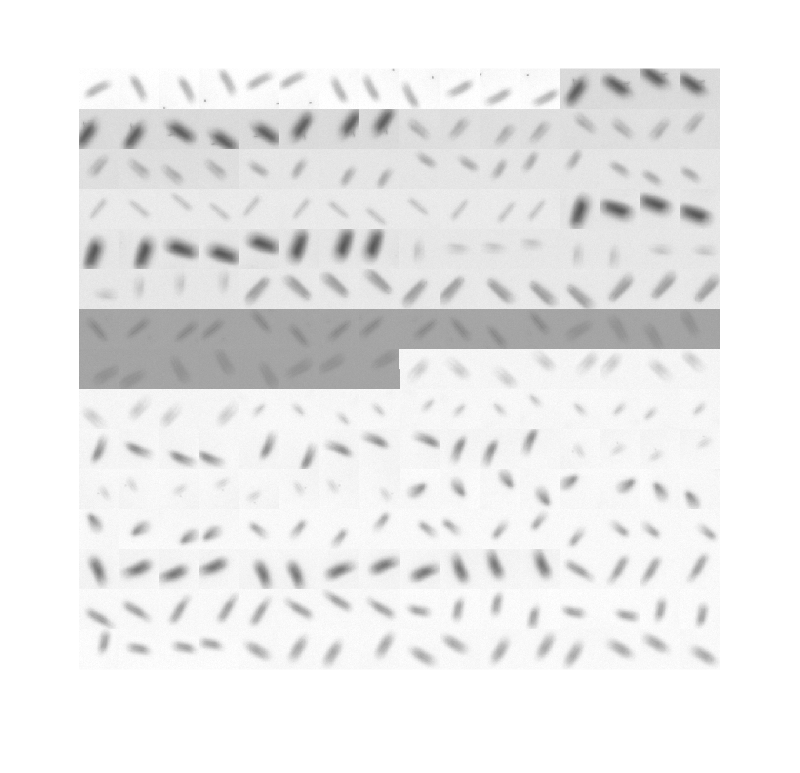

imshow(I(:,:,1));
[x,y] = ginput(1);
close all
x = round(x); y = round(y);
for i = 1:length(imds.Files)
    image_of_interested(:,:,i) = chopimage(I(:,:,i),x,y);
end
montage(image_of_interested);

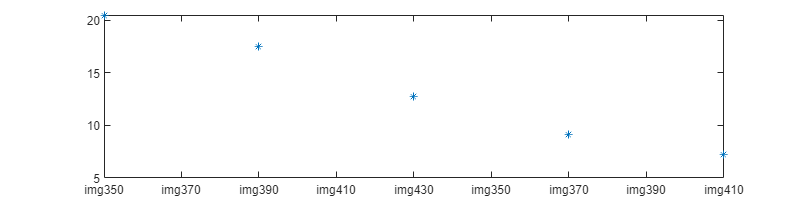

for i = 1:length(imds.Files)
    sharpness(i) = brenner(image_of_interested(:,:,i));
end
[filepath,name,ext] = fileparts(imds.Files);
plot(sharpness,'*')
x0=0;
y0=0;
width=800;
height=200;
set(gcf,'position',[x0,y0,width,height])
set(gca,'xticklabel',name')

sharpness

sharpness =    20.5100   17.4700   12.8000    9.1400    7.2000


maximum = max(max(sharpness));
[~,num] = find(sharpness == maximum);
disp(imds.Files(num));

    {'F:\research\deep learning\deep_learning_images\Quality Est\test100\img350.png'}

